# Bill and Ari Solar House Model

## Question

    According to [https://www.pnas.org/content/117/32/19122](https://www.pnas.org/content/117/32/19122), 20% of America’s greenhouse house gas emissions comes from household energy use, such as for climate control and appliance use. An efficient and comfortable solar house design would help greatly reduce household energy greenhouse gas emissions by reducing climate control energy needed. However, to have widespread adoption of solar houses, they need to be comfortable. This raises the question: how can we build the most comfortable passive solar house? 

    However, to answer this question, one must first answer the question of what is a comfortable house? While having a certain average temperature is nice, ultimately it doesn’t matter if your house averages at a comfortable 23deg C when it fluctuates between 0 deg C at night and 35 deg C during noon. Thus, here we define comfort as having the smallest temperature variations over time while remaining within a livable temperature rang, which we deifne here as between 15deg C and 25 deg C. 

    Thus, in this project we hope to find the optimal design for the passive solar house that maximizes comfort.

## Model

### Model Derviation:

    To answer our question, we will build a numerical model of a house that will allow us to simulate the house’s temperature over the span of a year given a set of parameters describing the house. Once we have this model, we can then parameter sweep to examine how different parameters affect the mean and range of the temperature within the house.

    The Department of Energy passive solar home design packet contains the following diagram illustrating the mechanisms for energy transport within a passive solar house:

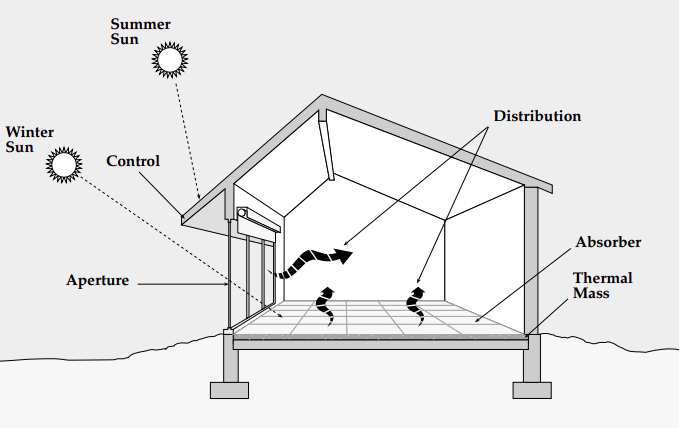

    For us to model this house while keeping the project within a reasonable scope, we have made a couple assumptions:

- For the structure of the house, we are assuming the only three materials used in the construction are concrete, polyurethane foam, and glass. In our model house, the walls are entirely made of foam, the floor is made entirely of concrete, with a layer of insulation underneath, and the aperture is entirely made of insulating glass.

- For the environment of the house, we are using an incredibly simple model for the temperature of the environment. The temperature of the ground is a single sinusoidal wave with a period of 1 year, and the temperature of the air outside is the temperature of the ground, with another 24 hour period sinusoid layered on top. This obviously drastically simplifies actual air and ground temperature changes.

- For our insolation model, we are making yet another major assumption: we are assuming that throughout the whole year the house is always pointed directly towards the sunrise, with the aperture being perpendicular to the path traveled by the sun. In the real world, the azimuth of the sun actually changes throughout the year, and so to build a house that constantly faces the sunrise one would have to mount the house on a giant turntable and rotate the house throughout the year.

    While these assumptions are all simplifications and abstractions, they do not fundamentally change the mathematical model of the house - it is only a matter of tweaking parameters, of numerical inaccuracy, Thus, while we will not be able to directly use the building design parameters generated by the model and the parameter sweeper, the conclusions we can draw from this project will still be valuable when considering how a passive solar house should be designed.

    From this set of abstractions, we can then build the model of the house represented here with our schematic drawing.

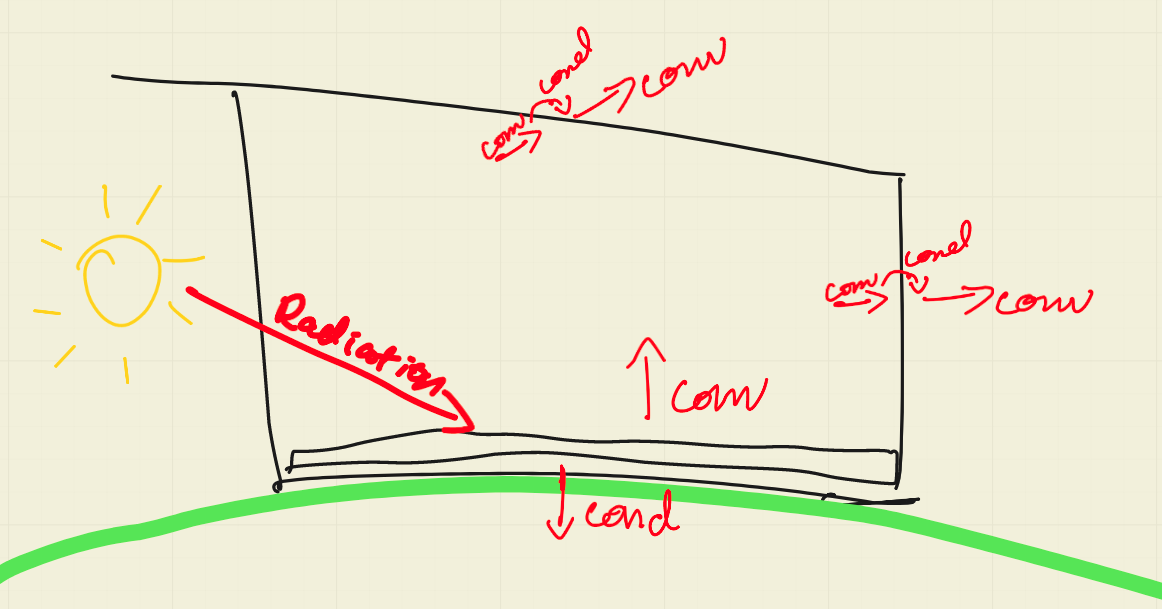

From this schematic, we can then generate a stock and flow diagram:

#### 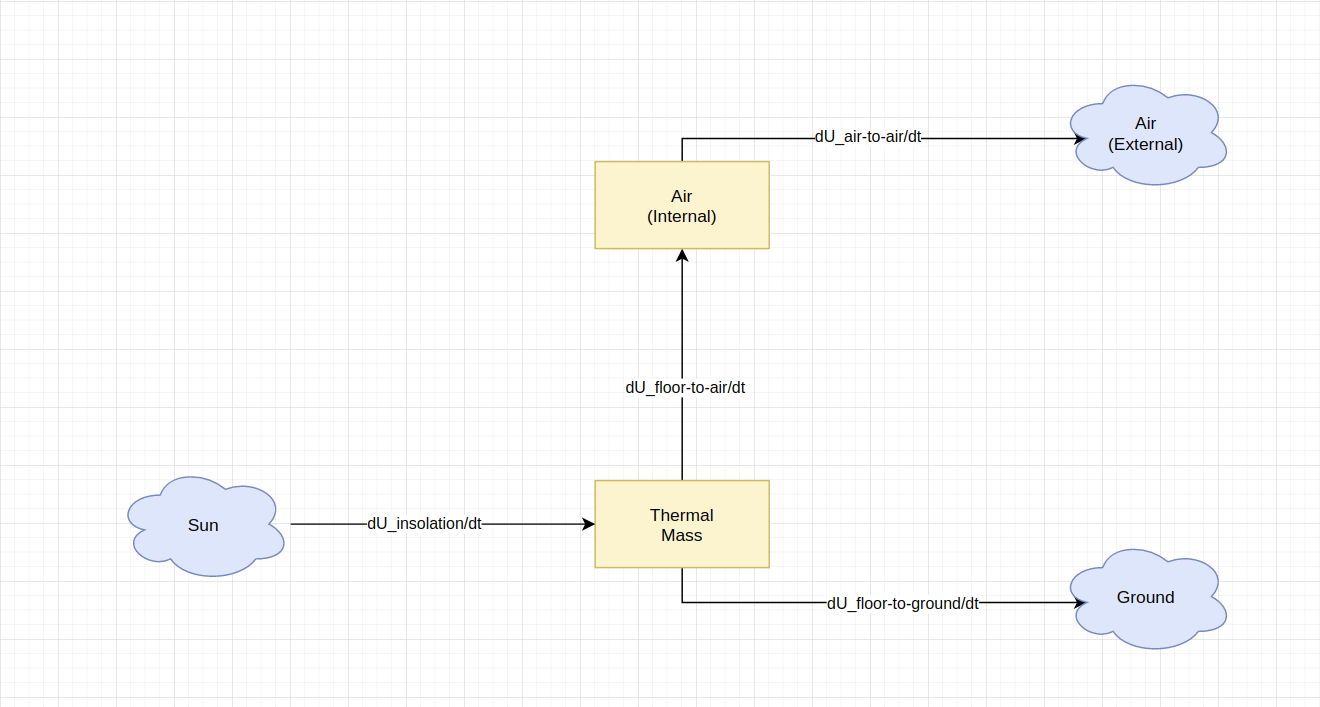

### Consolidated stock and flows:

From the stock and flow diagram we can then generate these equations for the total flows in and out of each stock:


$$\frac{dU_{air}}{dt} = \frac{dU_{floor-to-air}}{dt} - \frac{dU_{air-to-air}}{dt} \\

\frac{dU_{floor}}{dt} = \frac{dU_{insolation}}{dt} - \frac{dU_{floor-to-ground}}{dt} -  \frac{dU_{floor-to-air}}{dt} \\$$


### Equations for individual flows:

#### Energy flow from conduction/convection

General equation for heat flow when given resistances:


$$\frac{dU_{flow}}{dt} = \frac{-1}{R_{total}}\Delta T$$


For the individual heat flows, we then have:


$$\frac{dU_{floor-to-ground}}{dt} = \frac{-1}{R_{floor-to-ground}}(T_{ground} - T_{floor}) \\

\frac{dU_{floor-to-air}}{dt} = \frac{-1}{R_{floor-to-air}}(T_{air-inside} - T_{floor})\\

\frac{dU_{air-to-air}}{dt} = \frac{-1}{R_{air-to-air}}(T_{air-outside} - T_{air-inside})$$


#### Energy from radiation (insolation)

Equation for energy from insolation:


$$\frac{dU_{insolation}}{dt} = eIA_{insolation}$$


However, $A_{insolation}$ changes with time. In order to properly compute the energy radiated by the Sun, we need to calculate the angle of the sun perpendicular to the horizon as it rises and sets throughout the day (known as solar elevation or solar zenith). As mentioned above, we do not attempt to model the angle of the Sun parallel to the horizon (called solar azimuth), which varies over the course of the year.

The motion of the sun is a shockingly complex pattern, so the algorithm we use in this model (which a commonly-used one) is simply an approximation. It's generally accurate to within a few degrees of accuracy for lattitudes outside of the (ant)arctic cicles. The algorithm uses the longitude and latitude of the solar house, the "current" time, and the time zone to compute the precise solar time. This is then used to approximate the elevation of the sun.

Once we know the (approximate) angle of the Sun and the intensity of the Sun at the house's location (from imperical measurement), we can calculate the intensity of the solar radiation that hits our thermal. To do this, we take the actual area of our thermal mass and use some simple trigonometry to calculate the effective area, taking into account the angle of the sun and the size of the aperture:

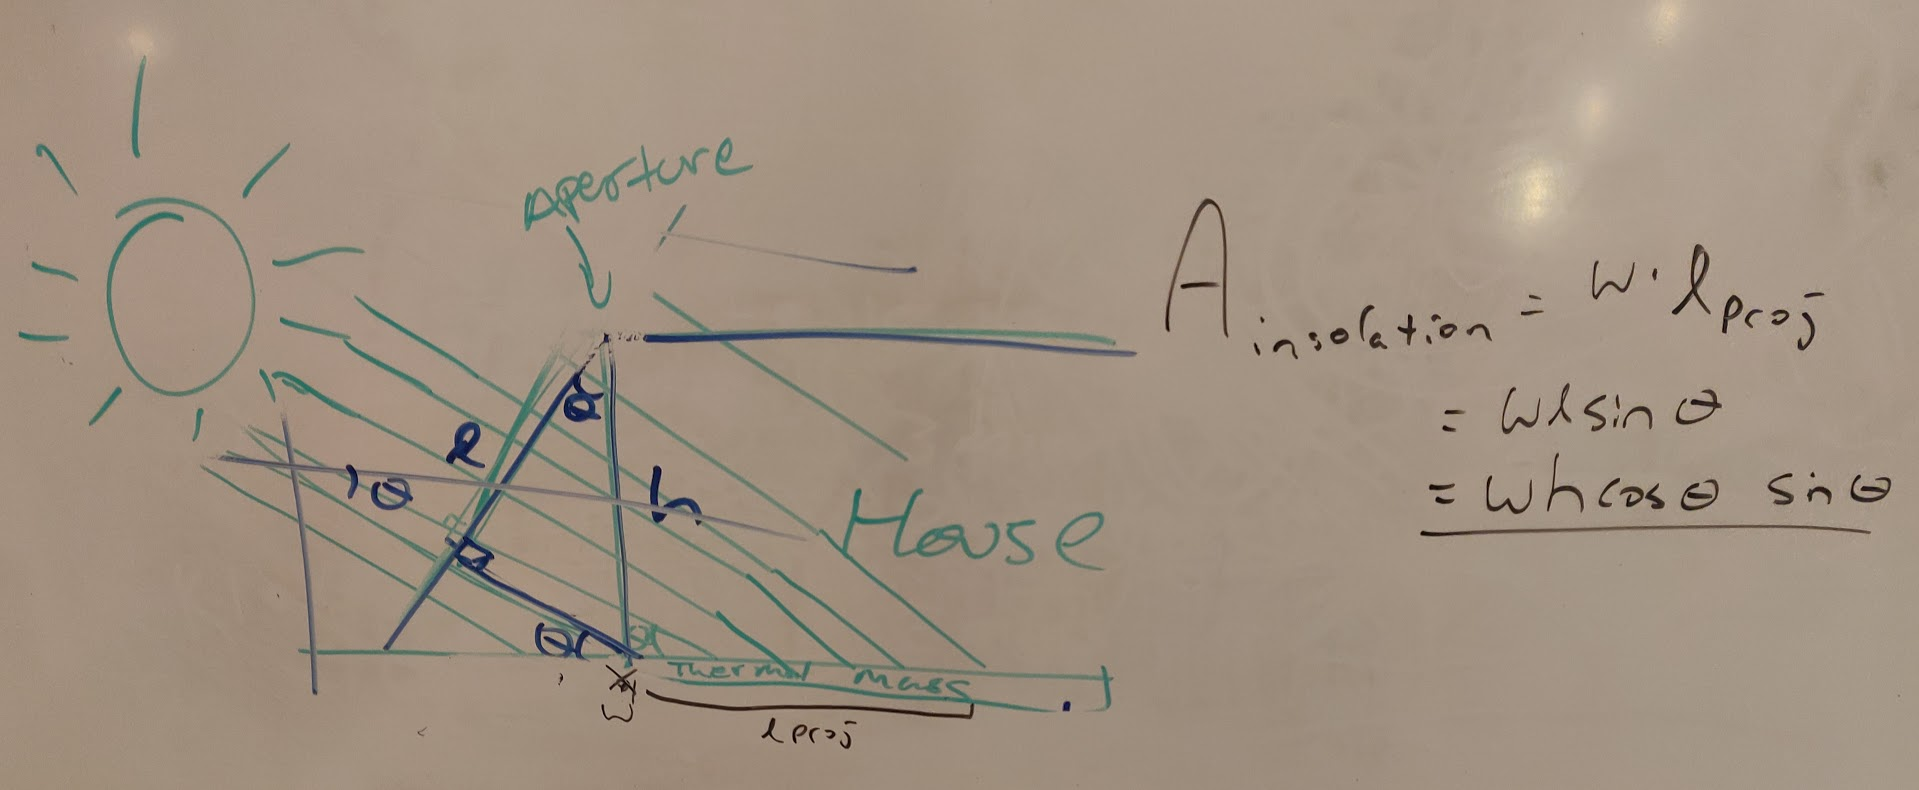

Giving us the equation (the width of the aperture is perpendicular to the whiteboard):


$$A_{\textrm{effective}} =w_{\textrm{aperture}} {\;\times \;h}_{\textrm{aperture}} \;\times \cos \left(\theta_{\textrm{Sun}} \right)\;\times \;\sin \left(\theta_{\textrm{Sun}} \right)$$


Now to implement these equations, we just need to derive the resistances, and find the temperatures in relation to energy

### Resistances:

$R_{air-air} = \frac{1}{2 \frac{1}{h_{air}(A_{w} + A_{ceil})} + \frac{d_{w}}{(A_{w} + A_{ceil})k_{w}} } + \frac{1}{2 \frac{1}{h_{air}A_{a}} + \frac{d_{a}}{A_{a}k_{a}} } \\
 = \frac{1}{2 \frac{1}{h_{air}(A_{w} + A_{f})} + \frac{d_{w}}{(A_{w} + A_{f})k_{w}} } + \frac{1}{2 \frac{1}{h_{air}A_{a}} + \frac{d_{a}}{A_{a}k_{a}} }$    and since the house is a box, $A_{ceil} = A_f $


$$R_{floor-air} = \frac{1}{h_{air} A_{f}}$$



$$R_{floor-ground} = \frac{d}{A_fk_f$$


### Temperatures:

The ground temperature doesn't really change much day-to-day, so we can create a rough model for it using a single cosine wave with a period of a year, amplitude of 10 deg C to account for seasonal temperature ranges, and shifted up 10 deg C. This also serves as the mean day-to-day temperature over the year. Now, to get the air temperature, we can just overlay another cosine wave with a period of 24 hours and an amplitude of 8 deg C to account for daily temperature ranges. These two waves create a rough approximation of ground and air temperatures over the course of a year. To put this into equation form:


$$T_{ground} = -10\ cos(\frac{2\pi t}{365 \cdot 24\cdot 60 \cdot 60}) + 10 + 273.15;$$



$$T_{air-outside} = T_{ground} - 4cos(\frac{2\pi t}{24 \cdot 60 \cdot 60})$$


$t$ being seconds since the start of the year.

For the other temperatures, based on the stocks, we can use the formula for converting energy into temperature: $U = mcT$. Thus,


$$T_{floor} = \frac{U_{floor}}{m_{floor}\ c_{floor}}$$



$$T_{air-inside} = \frac{U_{air-inside}}{m_{air-inside}\ c_{air}}$$


### Putting it all together


$$\frac{dU_{air}}{dt} = \frac{-1}{R_{floor-to-air}}(T_{air-inside} - T_{floor}) - \frac{-1}{R_{air-to-air}}(T_{air-outside} - T_{air-inside}) \\

\frac{dU_{floor}}{dt} = eIA_{insolation} - \frac{-1}{R_{floor-to-ground}}(T_{ground} - T_{floor}) - \frac{-1}{R_{floor-to-air}}(T_{air-inside} - T_{floor}) \\$$



$$T_{ground} = -10\ cos(\frac{2\pi t}{365 \cdot 24\cdot 60 \cdot 60}) + 10 + 273.15;$$



$$T_{air-outside} = T_{ground} - 4cos(\frac{2\pi t}{24 \cdot 60 \cdot 60})$$



$$T_{floor} = \frac{U_{floor}}{m_{floor}\ c_{floor}}$$



$$T_{air-inside} = \frac{U_{air-inside}}{m_{air-inside}\ c_{air}}$$



$$R_{air-air} = \frac{1}{2 \frac{1}{h_{air}(A_{w} + A_{f})} + \frac{d_{w}}{(A_{w} + A_{f}) k_{w}} } + \frac{1}{2 \frac{1}{h_{air}A_{a}} + \frac{d_{a}}{A_{a}k_{a}} }$$



$$R_{floor-air} = \frac{1}{h_{air} A_{f}}$$



$$R_{floor-ground} = \frac{d}{A_fk_f$$



$$A_{\textrm{effective}} =w_{\textrm{aperture}} {\;\times \;h}_{\textrm{aperture}} \;\times \cos \left(\theta_{\textrm{Sun}} \right)\;\times \;\sin \left(\theta_{\textrm{Sun}} \right)$$


### Model Verification

#### Basic Simulation

    For the first step of our model verification, let's run the simulation over the span of 2 days starting from January 1st, and just looking at how everything turns out. For the following simulations we will use these house parameters:

- Area: 350 sq meters

- Height: 5 meters

- Aperture/House length: 10 meters

- Floor/Thermal Mass thickness: 0.2 meters

- Wall/Insulation thickness: 0.2 meters

% Constant area
area_floor = 350;
height_aperture = 5;
width_aperture = 10;

% Parameters to sweep
thickness_floor = 0.2;
thickness_insulation = 0.3;

end_day = 2;
timespan = [1, end_day * (24 * 60 * 60)]; % Convert date time ranges to seconds
max_timestep = 1000;

[T_base, Y_base, debug] = house_simulate(timespan, max_timestep, height_aperture, width_aperture, area_floor, thickness_floor, thickness_insulation);

% Seconds to days
T_base = T_base / (24 * 60 * 60);
debug(:, 1) = debug(:, 1) / (24 * 60 * 60);

% K to C
Y_base(:, 1:2) = Y_base(:, 1:2) - 273.15;
debug(:, 6:7) = debug(:, 6:7) - 273.15;

% J to kJ
debug(:, 2:5) = debug(:, 2:5) / 1000;

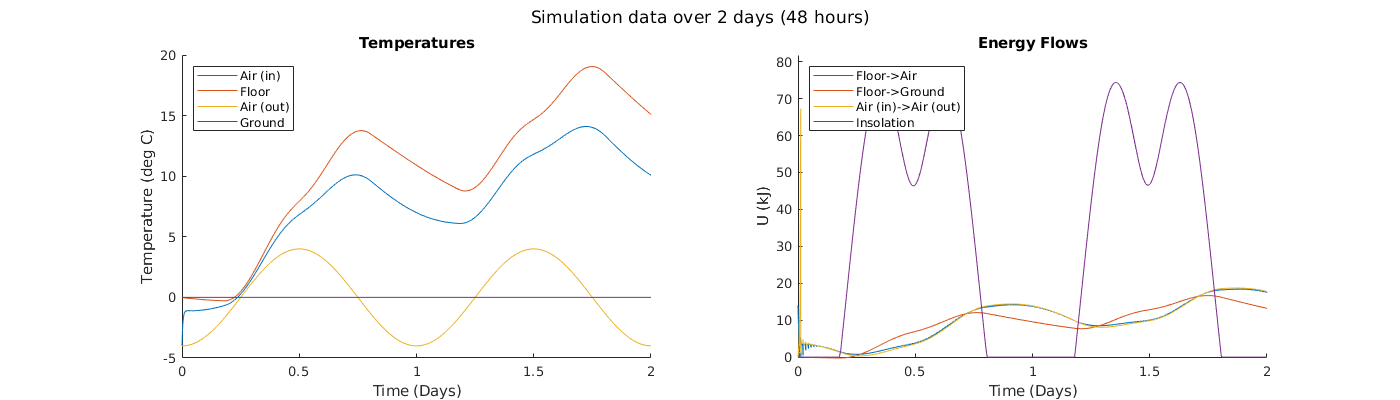

figure(1); clf;
set(gcf, 'position', [0 0 1400 400])
sgtitle('Simulation data over 2 days (48 hours)')

subplot(1, 2, 1);
hold on;
plot(T_base, Y_base(:, 1));
plot(T_base, Y_base(:, 2));
plot(debug(:, 1), debug(:,6))
plot(debug(:, 1), debug(:,7))
hold off;
legend("Air (in)", "Floor", "Air (out)", "Ground", 'location', 'nw');
xlabel("Time (Days)");
ylabel("Temperature (deg C)");
title("Temperatures");

subplot(1, 2, 2)
hold on;
plot(debug(:, 1), debug(:, 2))
plot(debug(:, 1), debug(:, 3))
plot(debug(:, 1), debug(:, 4))
plot(debug(:, 1), debug(:, 5))
hold off;
legend("Floor->Air", "Floor->Ground", "Air (in)->Air (out)", "Insolation", 'location', 'nw');
xlabel("Time (Days)");
ylabel("U (kJ)");
title("Energy Flows");

ylim([-0.25 max(max(debug))*1.1])

    Here we can see that the house's internal temperatures behave somewhat as expected: It rises during the day, and it falls during the night. Since the house started at a very cold temperature and contains a significant amount of thermal mass, the house achieves a net energy gain over this two day period. However, closer examination of the internal temperatures raises a question: If the house is facing the direction of the sunrise (east), why are the internal temperatures of the house still rising so much even after noon? Shouldn't the sun be over head, and thus not shining into the house anymore?

    The answer to this question lies in the energy flows plot. When we look at the insolation energy entering into the system over time, we notice a strange behavior: The solar energy starts to dip after mid morning, after the elevation/zenith passes 45 degrees, as the energy shrinks. This is normal. However, what is not normal is that 

- This shrinkage is not fast enough, as the energy is still 2/3 of the max energy at noon, when the sun is supposedly overhead and insolation area is 0

- Why in the world does the energy start to **rebound** after noon? It should be 0!!! And if not, at least it should be going down.

So it appears that our insolation model is wrong. However we realized this problem too late into the project to really figure out what is wrong with it. Plus, this addition in solar energy shouldn't really effect the conclusions drawn from the simulation significantly, only the numbers. Thus, we are leaving it as is.

#### Longer timespans

Now that we see that the simulation for a short 2 day timespan is reasonable, let's try simulating for a longer timespan:

timespan_1month = [1, 30 * (24 * 60 * 60)];
timespan_1year = [1, 365 * (24 * 60 * 60)];
max_timestep = 1000;

% Simulate for three different timespans
[T_1month, Y_1month, ~] = house_simulate(timespan_1month, max_timestep, height_aperture, width_aperture, area_floor, thickness_floor, thickness_insulation);
[T_1year, Y_1year, ~] = house_simulate(timespan_1year, max_timestep * 10, height_aperture, width_aperture, area_floor, thickness_floor, thickness_insulation);

% Seconds to days
T_1month = T_1month / (24 * 60 * 60);
T_1year = T_1year / (24 * 60 * 60);

% K to C
Y_1month(:, 1:2) = Y_1month(:, 1:2) - 273.15;
Y_1year(:, 1:2) = Y_1year(:, 1:2) - 273.15;

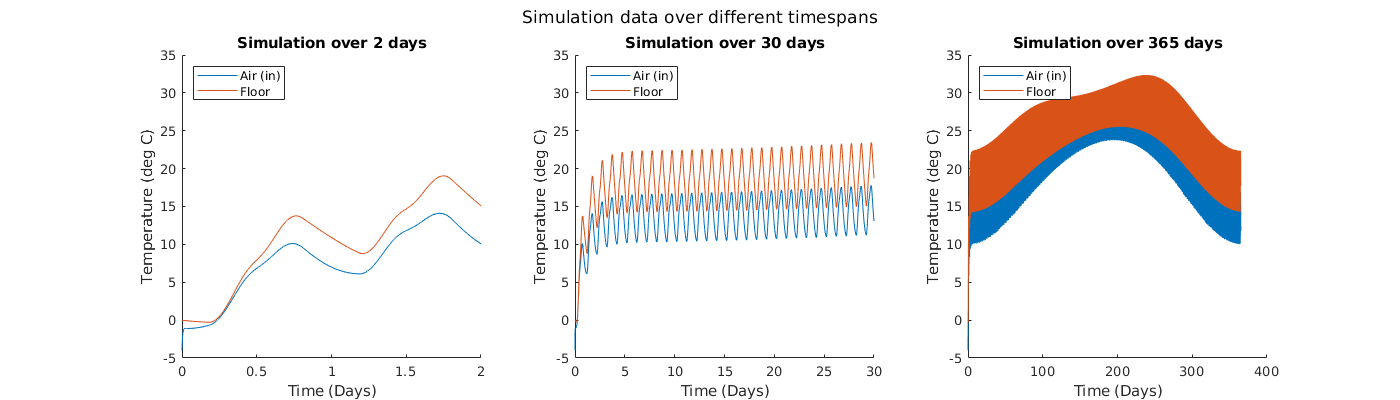

clf; figure(2);
set(gcf, 'position', [0 0 1400 400])
sgtitle('Simulation data over different timespans')

subplot(1, 3, 1);
hold on;
plot(T_base, Y_base(:, 1));
plot(T_base, Y_base(:, 2));
hold off;
legend("Air (in)", "Floor", 'location', 'nw');
xlabel("Time (Days)");
ylabel("Temperature (deg C)");
title("Simulation over 2 days");

subplot(1, 3, 2);
hold on;
plot(T_1month, Y_1month(:, 1));
plot(T_1month, Y_1month(:, 2));
hold off;
legend("Air (in)", "Floor", 'location', 'nw');
xlabel("Time (Days)");
ylabel("Temperature (deg C)");
title("Simulation over 30 days");

subplot(1, 3, 3);
hold on;
plot(T_1year, Y_1year(:, 1));
plot(T_1year, Y_1year(:, 2));
hold off;
legend("Air (in)", "Floor", 'location', 'nw');
xlabel("Time (Days)");
ylabel("Temperature (deg C)");
title("Simulation over 365 days");

fig2_axes = findall(gcf, 'type', 'axes');
linkaxes(fig2_axes, 'y');

    In these figures, we can note that as the timespans get longer, the behavior of the temperatures changes:

- Over a very short timeframe, the overall mean temperature of the house internals increases. As mentioned above, this reflects the house not being warm enough to release all the heat that it gains during the day

- Over a medium timeframe, we can notice that while the temperatures still oscillate over 24 hour periods, the temperature settles around an equillibrium. This is because as the house warms up, the temperature gradient between it and the outside world increases, increasing the amount of energy leaving the house. At a certain point, this energy flow gets high enough to match the amount of energy coming in from the sun, such putting the house at an equillibrium

- For the incredibly long timespan, we can see that the temperature follows a sinusoid with a year-long period. This is caused by the seasons changing, leading to increases in the average daily external temperatures, which reduces the energy lost by the house, increasing the house's internal temperatures as well

    In all of these cases, the house's temperatures behave exactly as expected. Thus, we can conclude that given our flawed insolation model, and a specific set of parameters, our house model behaves as expected. However, since our goal with the model is to use it to parameter sweep insulation and floor thicknesses to find an optimal combination, merely testing for a given set of parameters is not enough - we also need to check to see that when parameters are modified, the model changes as expected. For our model, this means changing the wall/insulation and floor/thermal mass thicknessess

timespan_10days = [1, 10 * (24 * 60 * 60)];
[T_thin, Y_thin, ~] = house_simulate(timespan_10days, max_timestep, height_aperture, width_aperture, area_floor, thickness_floor, thickness_insulation);

#### Increasing Insulation Thickness

    First we will increase the insulation thickness. Intuitively, increasing the thickness of the insulation should mean that the average temperature of the house will increase, as the house will be better at holding onto the heat energy that it contains. However, the house should still be just as vulnerable to day-night temperature changes, as the total heat capacity of the house is not increasing much. Here, we can simulate the house using 0.2m and 0.4m insulating foam, and compare the temperature values over time:

% Compare base case to thicker walls
[T_thickwalls, Y_thickwalls, ~] = house_simulate(timespan_10days, max_timestep, height_aperture, width_aperture, area_floor, thickness_floor, thickness_insulation * 2);

T_thin = T_thin / (24 * 60 * 60);
T_thickwalls = T_thickwalls / (24 * 60 * 60);

Y_thin = Y_thin - 273.15;
Y_thickwalls = Y_thickwalls - 273.15;

mean_thin = movmean(Y_thin(:, 1), length(Y_thin(:, 1)) / 10);
mean_thick = movmean(Y_thickwalls(:, 1), length(Y_thickwalls(:, 1)) / 10);

min_thin = movmin(Y_thin(:, 1), length(Y_thin(:, 1)) / 10);
min_thick = movmin(Y_thickwalls(:, 1), length(Y_thickwalls(:, 1)) / 10);

max_thin = movmax(Y_thin(:, 1), length(Y_thin(:, 1)) / 10);
max_thick = movmax(Y_thickwalls(:, 1), length(Y_thickwalls(:, 1)) / 10);

range_thin = max_thin - min_thin;
range_thick = max_thick - min_thick;

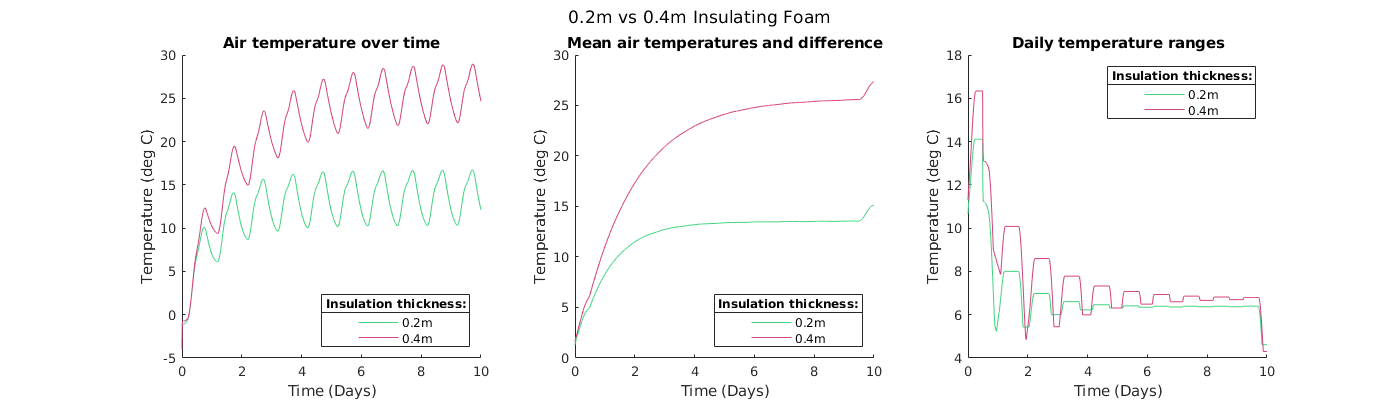

% Only plotting air
clf; figure(3);
set(gcf, 'position', [0 0 1400 400])
sgtitle('0.2m vs 0.4m Insulating Foam')

subplot(1, 3, 1);
hold on;
plot(T_thin, Y_thin(:, 1), 'Color', '#44d480');
plot(T_thickwalls, Y_thickwalls(:, 1), 'Color', '#d4447e');
lgd = legend('0.2m', '0.4m', 'Location', 'se');
title(lgd, 'Insulation thickness:');
title("Air temperature over time");
xlabel("Time (Days)");
ylabel("Temperature (deg C)");
hold off;

subplot(1, 3, 2);
hold on;
plot(T_thin, mean_thin, 'Color', '#44d480');
plot(T_thickwalls, mean_thick, 'Color', '#d4447e');
hold off;
lgd = legend('0.2m', '0.4m', 'Location', 'se');
title(lgd, 'Insulation thickness:');
title("Mean air temperatures and difference");
xlabel("Time (Days)");
ylabel("Temperature (deg C)");

subplot(1, 3, 3)
hold on;
plot(T_thin, range_thin, 'Color', '#44d480');
plot(T_thickwalls, range_thick, 'Color', '#d4447e');
lgd = legend('0.2m', '0.4m', 'Location', 'ne');
title(lgd, 'Insulation thickness:')
title("Daily temperature ranges")
xlabel("Time (Days)");
ylabel("Temperature (deg C)");
hold off;

         The third plot here needs a bit of explanation. The third plot is the difference between the rolling daily max temperatures and the rolling daily min temperatures. In short, it is the a rolling temperature range for a given house simulation.

    Here we can see that, as expected, the average temperature of the house has increased significantly, while the temperature range (min - max) has not. This means that increasing the wall/insulation thickness has the expected effect on the model system. 

#### Increasing Floor/Thermal Mass Thickness

    Now we will increase the floor/thermal mass thickness. Intuitively, increasing the thickness of the floor/thermal mass will have the opposite effect on the house's air temperature than increasing the wall thickness would have: since we're increasing the thermal capacity, the house will be more resistant against day-night temperature changes and thus have a smaller temperature range. However, this does not help increase the house's ability to hold onto heat, so the total temperature does not increase much. In fact, due to the larger thermal mass, it should in fact take the house longer to warm up to an equillibrium temperature than before. Let's run the simulation to see if these things are true:

% Compare base case to thicker floor
[T_thickfloor, Y_thickfloor, ~] = house_simulate(timespan_10days, max_timestep, height_aperture, width_aperture, area_floor, thickness_floor * 2, thickness_insulation);

T_thickfloor = T_thickfloor / (24 * 60 * 60);

Y_thickfloor = Y_thickfloor - 273.15;

mean_thin = movmean(Y_thin(:, 1), length(Y_thin(:, 1)) / 10);
mean_thick = movmean(Y_thickfloor(:, 1), length(Y_thickfloor(:, 1)) / 10);

min_thin = movmin(Y_thin(:, 1), length(Y_thin(:, 1)) / 10);
min_thick = movmin(Y_thickfloor(:, 1), length(Y_thickfloor(:, 1)) / 10);

max_thin = movmax(Y_thin(:, 1), length(Y_thin(:, 1)) / 10);
max_thick = movmax(Y_thickfloor(:, 1), length(Y_thickfloor(:, 1)) / 10);

range_thin = max_thin - min_thin;
range_thick = max_thick - min_thick;

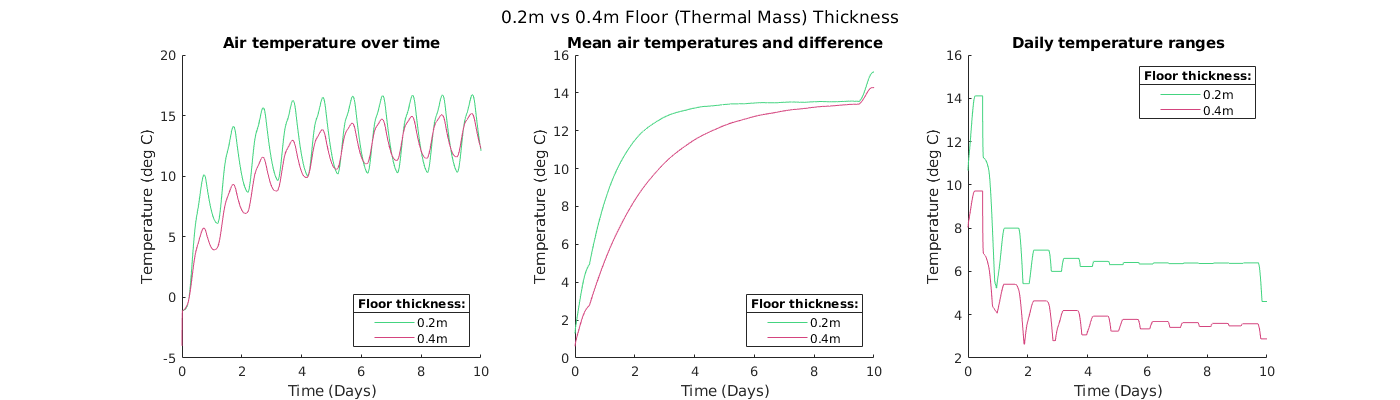

% Only plotting air
clf; figure(4);
set(gcf, 'position', [0 0 1400 400])
sgtitle('0.2m vs 0.4m Floor (Thermal Mass) Thickness')

subplot(1, 3, 1);
hold on;
plot(T_thin, Y_thin(:, 1), 'Color', '#44d480');
plot(T_thickfloor, Y_thickfloor(:, 1), 'Color', '#d4447e');
lgd = legend('0.2m', '0.4m', 'Location', 'se');
title(lgd, 'Floor thickness:')
title("Air temperature over time")
xlabel("Time (Days)");
ylabel("Temperature (deg C)");
hold off;

subplot(1, 3, 2);
hold on;
plot(T_thin, mean_thin, 'Color', '#44d480');
plot(T_thickfloor, mean_thick, 'Color', '#d4447e');
lgd = legend('0.2m', '0.4m', 'Location', 'se');
title(lgd, 'Floor thickness:');
title("Mean air temperatures and difference");
xlabel("Time (Days)");
ylabel("Temperature (deg C)");
hold off;

subplot(1, 3, 3)
hold on;
plot(T_thin, range_thin, 'Color', '#44d480');
plot(T_thickfloor, range_thick, 'Color', '#d4447e');
lgd = legend('0.2m', '0.4m', 'Location', 'ne');
title(lgd, 'Floor thickness:')
title("Daily temperature ranges")
xlabel("Time (Days)");
ylabel("Temperature (deg C)");
hold off;

    Once again, we can see that increasing the floor/thermal mass thickness has the expected effect on the house's air temperature: the air takes longer to reach equillibrium, the average temperature does not increase at all, but the daily temperature ranges have dropped significantly (by roughly 33%).

Now that we have seen that the house model simulation roughly matches a real passive house's thermal behavior, and responds to parameter changes in an expected fashion, we can confidently move onto model validation. This concludes our model's verification section.

### Validation

    Now that we have verified that our model makes logical sense, let's check the model against some real data. Here is data from [https://passipedia.org/basics/summer](https://passipedia.org/basics/summer) of a house in Darmstat, a city in southwestern Germany:

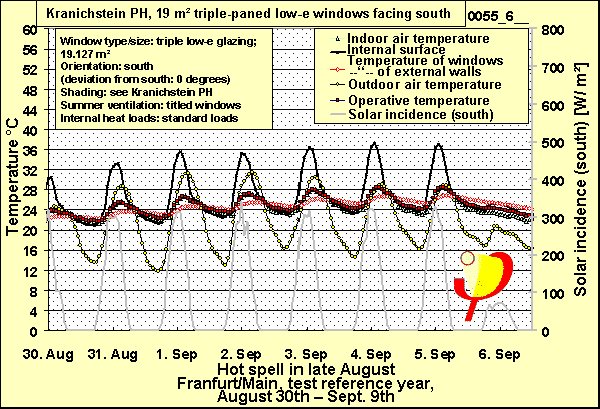

% Simulate sweep from day 240 to day 248
timespan_validation = [240 248] * (24 * 60 * 60);
[T_validation, Y_validation, debug_validation] = house_simulate(timespan_validation, max_timestep, height_aperture, width_aperture, area_floor, thickness_floor, thickness_insulation);

T_validation = T_validation / (24 * 60 * 60);
debug_validation(:, 1) = debug_validation(:, 1) / (24 * 60 * 60);

Y_validation = Y_validation - 273.15;
debug_validation(:, 6) = debug_validation(:, 6) - 273.15;
debug_validation(:, 7) = debug_validation(:, 7) - 273.15;

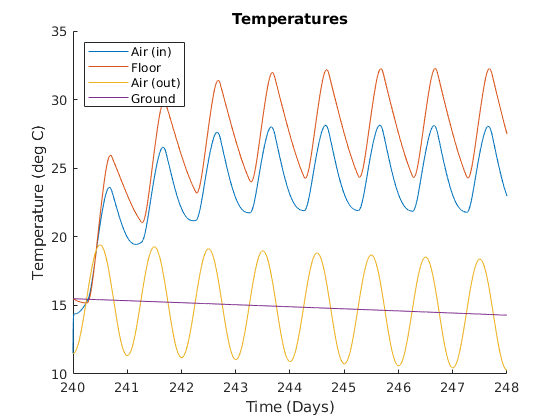

clf; figure(5)
hold on;
plot(T_validation, Y_validation(:, 1));
plot(T_validation, Y_validation(:, 2));
plot(debug_validation(:, 1), debug_validation(:,6))
plot(debug_validation(:, 1), debug_validation(:,7))
hold off;
legend("Air (in)", "Floor", "Air (out)", "Ground", 'location', 'nw');
xlabel("Time (Days)");
ylabel("Temperature (deg C)");
title("Temperatures");

Given that our house insulation and thermal mass parameters are not the same, our house's temperature changes over time matches that of the real passive solar house. This concludes our validation section.

## Results

Given that we're aiming to find the set of parameters that produces a solar house with the most stable temperature that is as close as possible to 20° C / 68° F / 293.15 K (hereafter, "room temperature"), we conducted a dual-dimensional parameter sweep for various thicknesses of both thermal mass and insulation. In order to concisely summarize the performance of each solar house, we calculate the average difference between the air temperature of the house in question and 293.15K over the course of the simulation (which, in this case, is 365 days). More formally, that's:


$$\textrm{AvgErr}=\frac{\int \left|293\ldotp 15K\;-{\textrm{Temp}}_{\textrm{air}} \right|\textrm{dt}\;}{t_f -t_i }$$


% Constant parameters
area_floor      = 210; % m^2, average US home size 
height_aperture =   3; % m
width_aperture  =  10; % m
ideal_temp = 20 + 273.15; % K (20C is room temperature)
max_step = 1000; % maximum number of seconds ODE45 can calculate at once

% Parameters to sweep
floor_thicknesses = 0.5:0.5:5;
insulation_thicknesses = 0.15:0.01:0.3;

% How long should the simulation run for?
length_sweeper = 365; % days
% We let the simulation run for several days before we start analyzing the
% data, because the stocks and flows are initially quite variable before
% settling into the long-term equilibrium that we care about. This is a
% combination of a real-world phenomenon and imprecise initial values. We
% decided that spending lots of time iterating on these starting values
% wasn't important for the learning goals, so we do this kludge instead.
pre_days = 45; % days

% Convert the options above into the format required by the sweeper
timespan = [1, pre_days + 1, length_sweeper + pre_days + 1] * (24 * 60 * 60); % days -> seconds

% Let's run some simulations!
cumulative_errors = house_sweep(timespan, max_step, height_aperture, width_aperture, area_floor, floor_thicknesses, insulation_thicknesses, ideal_temp);

Running a parameter sweep with 80 simulations...


Done with sweep! Ran 80 simulations! Took 140.35 seconds (avg 1.73s each).


Now, let's actually do some plotting! These graphs both show the same data, but in different ways. Notice that the thickness of the insulation has a very significant effect on the average error, while the thickness of the thermal mass has a much less significant—but very strongly correlated—effect.

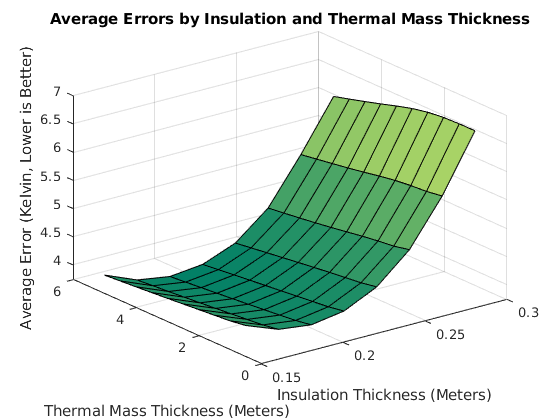

%% Plot the cool mesh
figure; clf;

[x_axis, y_axis] = meshgrid(insulation_thicknesses, floor_thicknesses);
surf(x_axis, y_axis, cumulative_errors); hold on;

colormap summer;

title("Average Errors by Insulation and Thermal Mass Thickness");
xlabel("Insulation Thickness (Meters)");
ylabel("Thermal Mass Thickness (Meters)");
zlabel("Average Error (Kelvin, Lower is Better)");

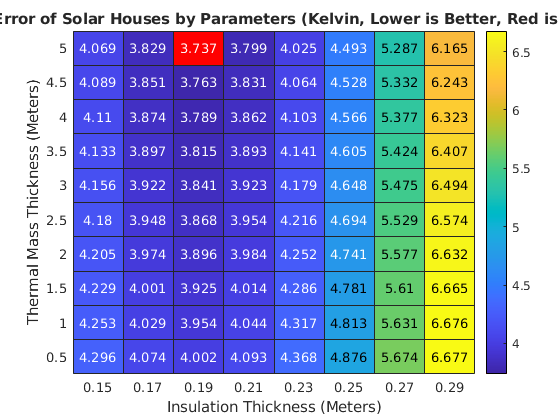


%% Plot the Heatmap
figure; clf;

hmap = heatmap(insulation_thicknesses, floor_thicknesses, cumulative_errors);
% By default, the lowest value isn't in the bottom left of the heatmap, so
% we flip the Y-axis.
hmap.YDisplayData = flip(floor_thicknesses);

xlabel("Insulation Thickness (Meters)");
ylabel("Thermal Mass Thickness (Meters)");
title("Average Error of Solar Houses by Parameters (Kelvin, Lower is Better, Red is Lowest)");

% We want the lowest (best) value to be a different color (specifically,
% red), so we switch to a specific color map that doesn't include red, then
% modify it to have red as the very lowest value. This isn't always 100%
% perfect--there's often more than one red value--but it's good enough.
colormap default;
colormap([1 0 0; colormap()]);

## Interpretation

The result of our model dictates that the ideal solar house has approximately 0.2 meters of insulation and as much thermal mass as is feasibly possible (although the quantity of thermal mass is far less impactful than the amount of insulation). This house, on average, will be 20±3.75° C (61.25-74.75° F) without any additional heating or cooling. Both ends of that temperature range are entirely livable for humans, meaning that a purely passive solar house could be a viable and eco-friendly home.

While it's frustrating that we couldn't find a magic balance that makes a perfect solar home, that not-black-and-white outcome is far more reflective of reality. Overall, we believe our answer to be relatively strong, except insofar as it is limited by the limitations of our model. To that end, we are somewhat suspicious of the fact that our model claims that a solar house could be highly functional all year round in Needham, MA—which intuitively seems improbable. Intuition isn't a reason to throw out science, and we still believe that our results are correct within the confines of our model. However, we think that further investigation (see below) might be needed to fully resolve this discrepancy.

As we know, no model is perfect, and ours has many limitations, including:

- We assume that the house is composed exclusively of glass, insulating foam, and concrete. Presumably, a real solar home would include many other things too (both building materials and contents).

- We have a relatively simple model of external air temperature, that doesn't take into account weather patterns. Additionally, it doesn't take into account (for example) the potential thermal effects of snow.

- Our model of insolation doesn't include solar azimuth, or the angle of the sun parallel to the horizon. This would likely have a substantial effect on the amount of energy received by the solar mass.

- We don't consider anything (people, furniture, etc.) inside the house, which would likely substantially affect both the specific heat of the house and the amount of insolation the thermal mass receives.

- We assume that the house is a perfect box, which is unlikely to be the case for a real house.

For a future iteration of our model, we would begin by improving our model of weather and external air temperature. In practice, we know that these have a large effect on the heating and cooling of any house (solar or otherwise), but our model doesn't account for them. In particular, modeling cloud cover and precipitation (especially snow) would be important next steps. Additionally, we think that adding a model of solar azimuth might have a substantial impact on the thermals of the house, but we cannot be confident in that without trying it. Finally, we think that including some measure of cost (of the thermal mass cement, of the insulation, and of active heating and cooling), could produce an interesting model for optimizing the total cost of ownership for a solar home, but that is ultimately a different question than the one we set out to answer.